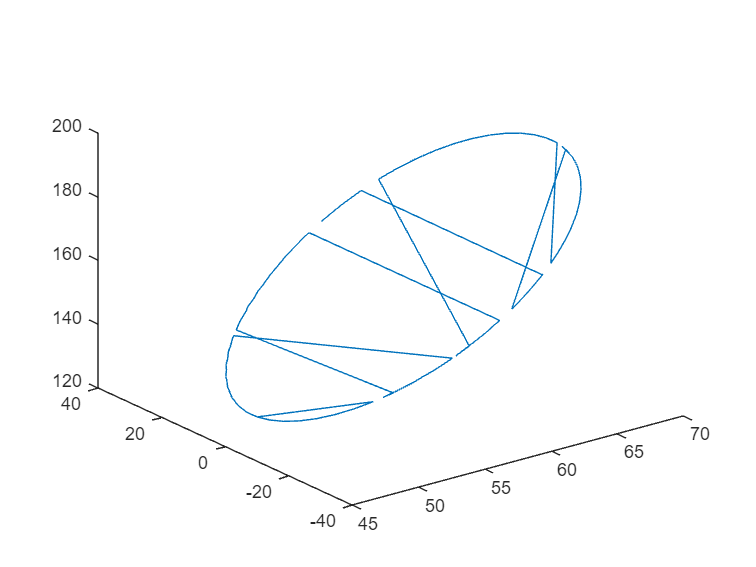

load('matlab.mat')

% for i=1:40
%     % compute (unordered) level sets
%     %[level_time{i},triidx] = compute_level_set4_KP(TR_start,edges_unique,levelT2(i),vint,[]);
%     points = level_time{i,1};
%     points = pc_rotate(points);
%     plot3(points(:,1),points(:,2),points(:,3))
%     pause(1)
% 
%     hold on
%     %skel(i,:) = mean(level_time{i},2)';
% end

% load('matlab.mat')
points = level_time{25,1};
pc = points;
plot3((points(1,:)),(points(2,:)),(points(3,:)))

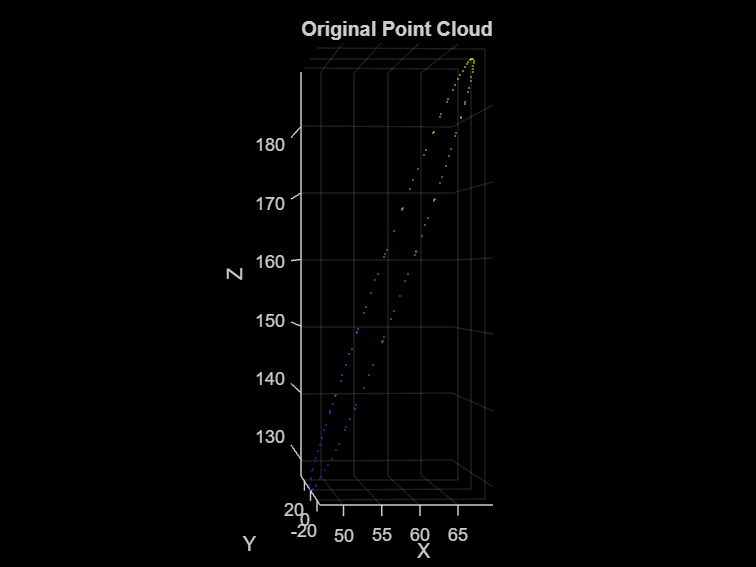

P1 = points(:,1);
P2 = points(:,110);
P3 = points(:,65);
% Calculate the normal vector of the circle's plane
v1 = P2 - P1;
v2 = P3 - P1;
normal = cross(v1, v2);
normal = normal / norm(normal);
% Define the normal vector of the XY plane
normalXY = [0, 0, 1]; % Assuming the XY plane is the standard plane
% Calculate the dot product between the two normal vectors
dotProduct = dot(normal, normalXY);
% Calculate the angle between the two planes in radians
angleRad = acos(dotProduct);
% Convert the angle to degrees
angleDeg = rad2deg(angleRad);
% 
% 
% % Extract XYZ coordinates
pc = pointCloud(pc');
% 
% % Calculate the center
% center1 = mean(points');
% 
% % Display the center coordinates
% % disp(['Center coordinates: (', num2str(center(1)), ', ', num2str(center(2)), ', ', num2str(center(3)), ')']);
% 
% %rotation of point cloud
% rotationAngles = [0,angleDeg, 0];
% translation = [0 0 0];
% tform = rigidtform3d(rotationAngles,translation);
% ptCloudOut = pctransform(pointCloud(points'),tform);
% center2 = mean(pointCloud(points').Location);
% 
% %rotation of point cloud
% rotationAngles = [0,0, 0];
% translation = [center2(1)-center1(1), center2(2)-center1(2), center2(3)-center1(3)];
% tform = rigidtform3d(rotationAngles,translation);
% ptCloudOut = pctransform(pointCloud(points'),tform);
% 
% pcshow(pointCloud(points'))
% 
% pcshow(ptCloudOut)


% Step 1: Define the point cloud
% Assuming you have a matrix called 'pointCloud' with [x, y, z] coordinates

% Step 2: Define rotation parameters
theta = pi/4;  % Rotation angle (45 degrees)
axisVec = [0, 0, 1];  % Rotation axis (around z-axis)

% Step 3: Apply rotation transformation
% rotationMatrix = axang2rotm([axisVec, theta]);  % Convert rotation parameters to rotation matrix
rotationAngles = [0,-15 , 0];
translation = [0 0 0];

 
tform = rigidtform3d(rotationAngles,translation);  % Create an affine transformation object
rotatedPointCloud = pctransform(pc, tform);  % Apply the transformation to the point cloud

% Visualize the original and rotated point clouds
figure;
pcshow(pc);
title('Original Point Cloud');
xlabel('X')
ylabel('Y')
zlabel('Z')
view([-4.0 0.0])

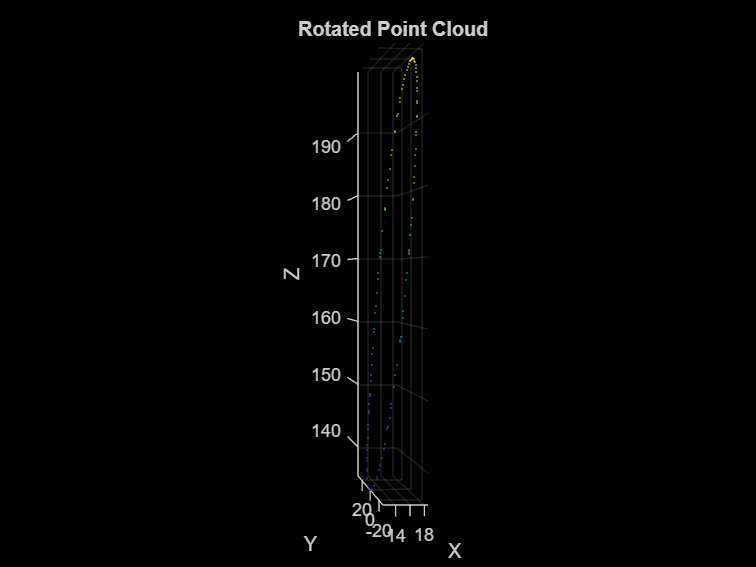


figure;
pcshow(rotatedPointCloud);
title('Rotated Point Cloud');
xlabel('X')
ylabel('Y')
zlabel('Z')
view([-4.0 0.0])